# **Visión Artificial. GIEC-GITT.**

# **Sistemas de Visión Artificial. GII-GIC-GISI.**

 **Sira Palazuelos, Miguel Angel Garcia, Juan Manuel Miguel**

 **Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Alejandro Fernández Ambrós, Cristina Martínez Toledo**

**Fecha: 20/11/2026**

# Tema 4. Ejercicio 5. Texturas

El objetivo de este ejercicio es la caracterización de texturas. Para ello, sobre imágenes con texturas diferentes, se obtendrán y compararán los valores de entropía, las matrices de coocurrencia en niveles de gris (GLCM) y diferentes estadísticas obtenidas a partir de las GLCM para diversos vectores de desplazamiento (*offset)*.

%% Paso 1: lectura de las imágenes

Paso 1) Lectura de las imágenes.

clear all
close all
% textures from http://www.cb.uu.se/~gustaf/texture/
imagenames = {'texture-stone.png','texture-sand.png','texture-linseeds.png', ...
              'texture-canvas.png','texture-pattern1.png','texture-pattern2.png'};

textureImg = cell(1, numel(imagenames));
for n = 1:numel(imagenames)
    textureImg{n} = im2gray(imread(imagenames{n}));
end


## Paso 2: entropía

Paso 2) **Entropía:** Calcule la entropía de las imágenes de patrones *textureImg* leídas en el paso anterior (usando la función `entropy)`, y ordénelas (usando la función `sort)`, en orden creciente de entropía (de la más baja a la más alta) y muestre las imágenes y su entropía según dicho orden. ¿Qué imagen tiene la menor entropía? Relacione el resultado con la distribución de sus niveles de gris y justifique sus conclusiones.


valoresEntropia = zeros(numel(textureImg), 1);
for n = 1:numel(textureImg)
    valoresEntropia(n) = entropy(textureImg{n});
end
[entropiaOrdenada, orden] = sort(valoresEntropia);
nombresOrdenados = imagenames(orden);
tablaEntropia = table(nombresOrdenados(:), entropiaOrdenada, ...
    'VariableNames', {'Imagen', 'Entropia'})

tablaEntropia = 6×2 table
    'texture-pattern2.png'    4.1983
    'texture-pattern1.png'    4.7936
      'texture-canvas.png'    5.9055
        'texture-sand.png'    6.5980
       'texture-stone.png'    6.8046
    'texture-linseeds.png'    7.2660


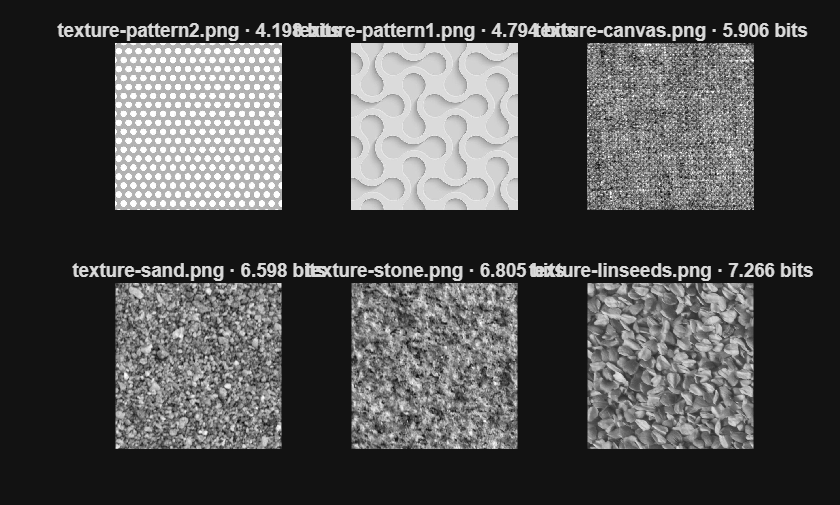


figure
for n = 1:numel(orden)
    subplot(2, 3, n)
    imshow(textureImg{orden(n)})
    title(sprintf('%s · %.3f bits', imagenames{orden(n)}, entropiaOrdenada(n)), ...
        'Interpreter', 'none')
end

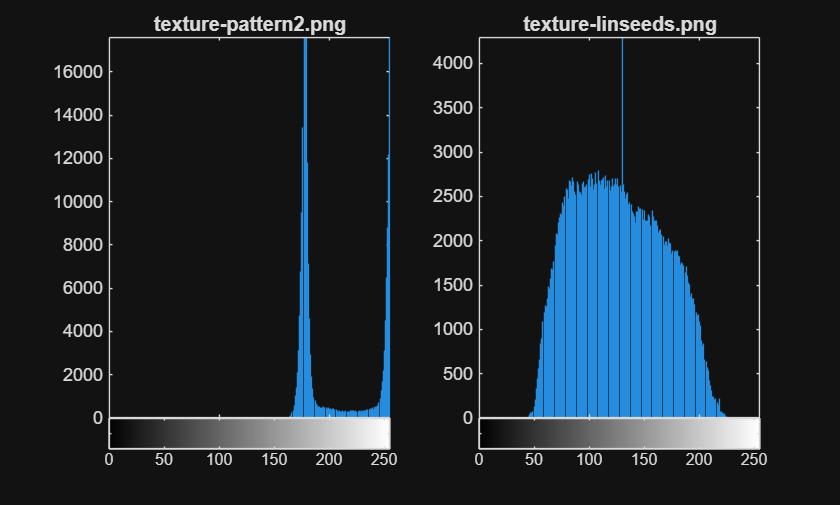


% Los dos extremos del orden permiten ver cómo se reparte el gris.
figure
extremos = orden([1 end]);
for n = 1:numel(extremos)
    subplot(1, 2, n)
    imhist(textureImg{extremos(n)})
    title(imagenames{extremos(n)}, 'Interpreter', 'none')
end

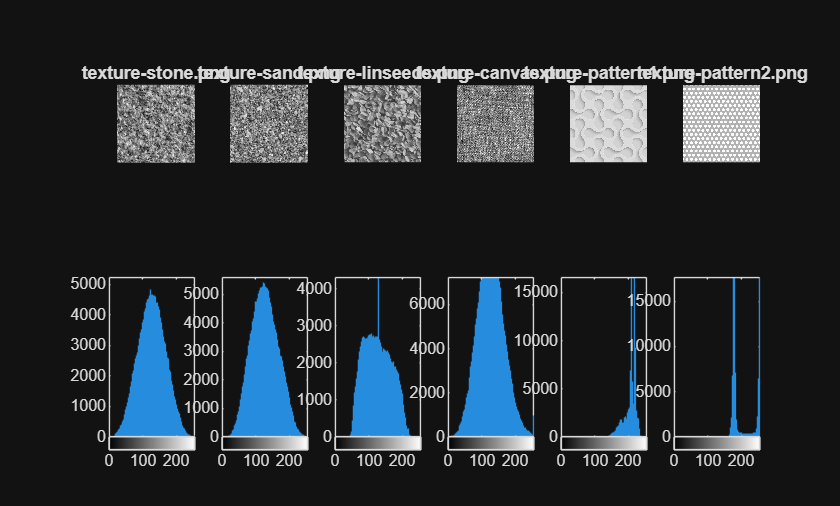


% Prueba extra: histogramas de todas las texturas
figure
for n = 1:numel(textureImg)
    % Fila de arriba: la imagen
    subplot(2, numel(textureImg), n)
    imshow(textureImg{n})
    title(imagenames{n}, 'Interpreter', 'none')

    % Fila de abajo: su histograma
    subplot(2, numel(textureImg), numel(textureImg) + n)
    imhist(textureImg{n})
end

La entropía mide cómo de repartidos están los grises en el histograma de la imagen: si todos los píxeles tuvieran el mismo gris, la entropía sería de 0, mientras que si los 256 grises aparecieran por igual, la entropía sería de 8 bits, el máximo (cualquier gris es igual de probable).

`texture-pattern2.png` tiene la entropía más baja (4,198 bits). En la primera imagen se ve hileras de círculos claros, todos parecidos, sobre un fondo gris bastante uniforme. Eso se reconoce en el histograma como dos zonas de concentración, una alrededor del gris del fondo y otra en el extremo claro de los círculos. En `texture-linseeds.png`, que tiene la entropía más alta (7,266 bits), los valores ocupan un intervalo bastante más amplio. En la foto de las semillas se distinguen zonas claras en la superficie de cada semilla, bordes a media luz y sombras oscuras entre ellas. En el histograma esa variedad se ve como un bloque ancho de barras en lugar de unos pocos picos estrechos. Si elegimos un píxel al azar, es más fácil anticipar su gris en el patrón de círculos.

La entropía solo depende del histograma, es decir, de qué niveles de gris aparecen y en qué proporción, pero no de cómo están colocados los píxeles en la imagen. Por eso, dos texturas distintas pueden tener histogramas y entropías muy parecidos. Es lo que ocurre con texture-stone.png y texture-sand.png: ambas tienen un histograma en forma de campana centrado en el mismo gris medio y con la misma dispersión, y sus entropías son muy próximas (6,80 y 6,60 bits). Sin embargo, visualmente son texturas diferentes: la piedra presenta manchas claras y oscuras de mayor tamaño, mientras que la arena está formada por granos mucho más finos. La diferencia está en cómo se distribuyen espacialmente los grises, algo que la entropía no puede detectar. Para caracterizar esa organización espacial se necesitan estadísticos de segundo orden, como los obtenidos a partir de la matriz de coocurrencia (GLCM) en los pasos siguientes.

## Paso 3: matrices de coocurrencia

Paso 3) **GLCM (Matriz de coocurrencia de niveles de gris).** Lea la ayuda de la función `graycomatrix` para entender todos sus parámetros ([https://es.mathworks.com/help/images/ref/graycomatrix.html](https://es.mathworks.com/help/images/ref/graycomatrix.html)). Defina los vectores de desplazamiento (`offsets`) correspondientes a las direcciones 0°, 45°, 90° y 135°, utilizando `len=5`. Utilícelos para calcular el conjunto de matrices de coocurrencia (GLCMs), usando la función `graycomatrix` sobre los ficheros anteriores. Puede serle útil consultar el código del ejemplo "**Calcular GLCM utilizando cuatro desfases diferentes"** de la ayuda de la función `graycomatrix`. Compruebe en la ayuda qué número de niveles de gris utiliza `graycomatrix` por defecto y relacione este comportamiento con lo estudiado en teoría.

len = 5;
angulos = [0 45 90 135];
% Cada fila es [desplazamiento en filas, desplazamiento en columnas].
% Una fila negativa sube en la imagen.
offsets = [ 0   len;     %  0°: misma fila, len a la derecha
           -len len;     % 45°: len arriba y len a la derecha
           -len  0;      % 90°: len arriba
           -len -len];   % 135°: len arriba y len a la izquierda
glcm = cell(1, numel(textureImg));
for n = 1:numel(textureImg)
    glcm{n} = graycomatrix(textureImg{n}, 'Offset', offsets);
end

Según la ayuda de graycomatrix, por defecto se usan 8 niveles de gris (NumLevels = 8), repartidos de forma uniforme en el rango de la clase de la imagen, de 0 a 255 en uint8 (GrayLimits). Cada nivel agrupa 32 valores de gris consecutivos  (0-31 es el nivel 1, 32-63 el nivel 2…), y para cada desplazamiento se obtiene una matriz de 8 × 8.

Esto se relaciona con lo visto en teoría: el tamaño de la GLCM es k × k, siendo k el número de niveles de gris. Con los 256 niveles originales la matriz tendría 65 536 celdas, la mayoría con recuentos muy bajos o nulos, y sería poco manejable y muy sensible al ruido. Cuantificar la imagen a un número menor de niveles agrupa los recuentos y da una matriz más compacta y estable. Como contrapartida, se pierden las diferencias de gris pequeñas.

Como los límites son fijos, las imágenes con poco rango solo usan parte de los niveles. Por ejemplo, texture-pattern2.png tiene grises entre 158 y 255 y solo ocupa los niveles 6 a 8.

Los valores de la diagonal cuentan parejas del mismo nivel de gris agrupado.

## Paso 4: comparar visualmente las GLCM

Paso 4) Visualice la primera GLCM, correspondiente al primer offset, utilizando colores escalados. Observe cómo se distribuyen sus valores y compárela con las GLCM correspondientes a otros vectores de desplazamiento. Para ello puede adaptar el código siguiente:

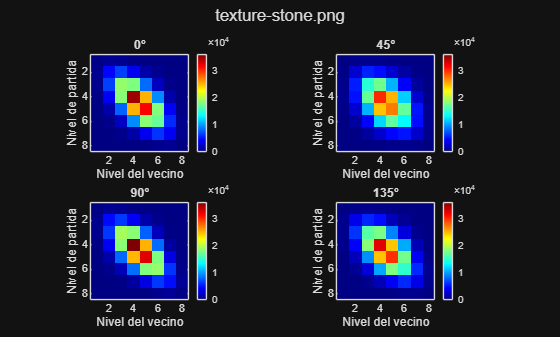

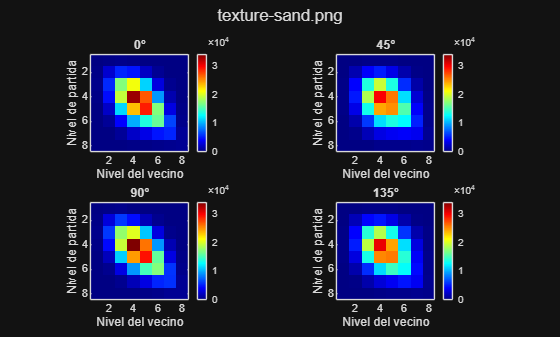

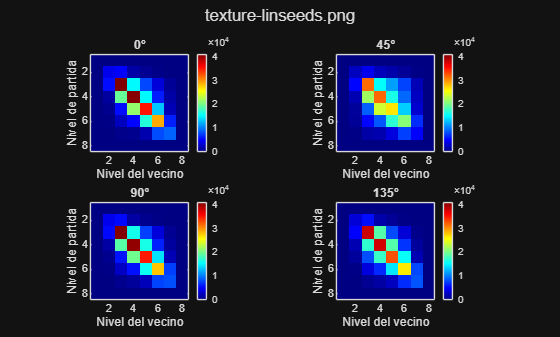

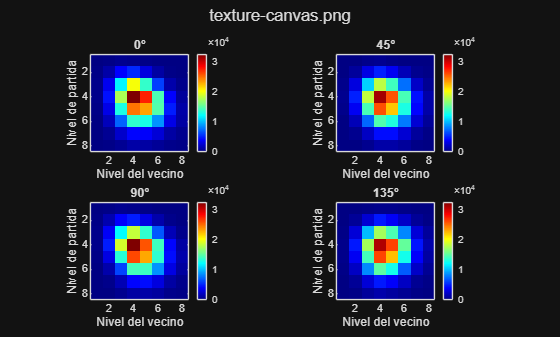

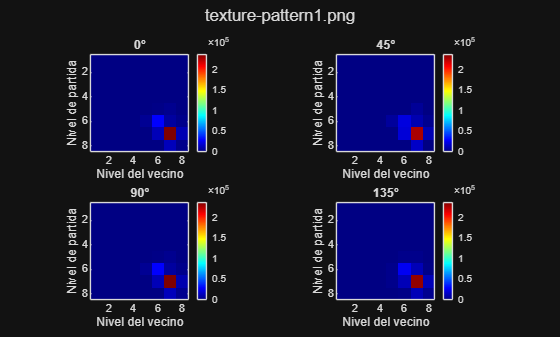

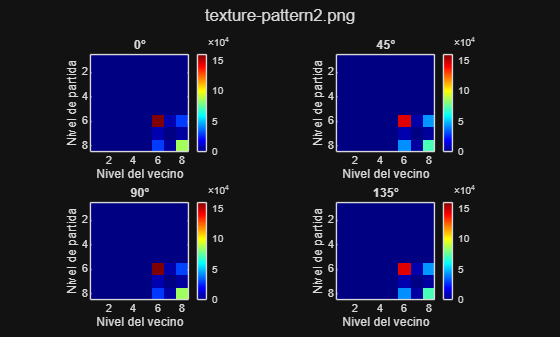

for n = 1:numel(textureImg)
    figure
    % Una sola escala de color para comparar las cuatro direcciones.
    escala = [0 max(glcm{n}(:))];
    for d = 1:numel(angulos)
        subplot(2, 2, d)
        imagesc(glcm{n}(:, :, d), escala)
        axis image
        colorbar
        xlabel('Nivel del vecino')
        ylabel('Nivel de partida')
        title(sprintf('%d°', angulos(d)))
    end
    colormap jet
    sgtitle(imagenames{n}, 'Interpreter', 'none')
end

En `texture-pattern2.png` casi todo se concentra entre los niveles 6 y 8. A 0° y 90° destacan las parejas de gris parecido en la diagonal. A 45° y 135° ganan peso algunas parejas entre niveles distintos, como las celdas (6, 8) y (8, 6). En el mapa se ve que se iluminan las dos casillas que quedan a los lados de la diagonal. Corresponden a saltos entre el fondo gris y la parte clara del patrón. En `texture-linseeds.png` los recuentos se reparten entre más niveles. A 0° y 90° se ve una franja diagonal más marcada, mientras que a 45° los recuentos se extienden más fuera de ella. Al comparar los dos paneles superiores, a 0° las casillas más cálidas forman una línea definida y a 45° se reparten en una zona más ancha. Ese cambio visual coincide con el mayor contraste que sale en la tabla.

En la piedra y la arena, a 0° y 90° resaltan más las parejas del mismo nivel. En las diagonales ganan peso las celdas de alrededor. La tela cambia poco y mantiene los recuentos principalmente en los niveles intermedios, mientras que en `texture-pattern1.png` domina la pareja (7, 7) en las cuatro direcciones.

## Paso 5: estadísticos por dirección

Paso 5) Obtenga y visualice los estadísticos  `Contrast, Correlation, Energy y Homogeneity` de las GLCM utilizando la función `graycoprops` para las imágenes `'texture-linseeds.png'` y `'texture-pattern2.png'` utilizando las GLCM correspondientes a los diferentes vectores de desplazamiento definidos anteriormente.

Compare los valores obtenidos para las dos texturas y para los diferentes offsets. ¿Qué propiedades cambian al modificar la dirección del desplazamiento? Relacione los resultados con las características visuales de las dos texturas.



comparar = {'texture-linseeds.png', 'texture-pattern2.png'};
tablas = cell(1, numel(comparar));
for n = 1:numel(comparar)
    indice = find(strcmp(imagenames, comparar{n}));
    medidas = graycoprops(glcm{indice}, 'all');
    textura = repmat(comparar(n), numel(angulos), 1);
    tablas{n} = table(textura, angulos(:), medidas.Contrast(:), ...
        medidas.Correlation(:), medidas.Energy(:), medidas.Homogeneity(:), ...
        'VariableNames', {'Textura', 'Direccion', 'Contraste', 'Correlacion', 'Energia', 'Homogeneidad'});
end
tablaGLCM = vertcat(tablas{:})

tablaGLCM = 8×6 table
    'texture-linseeds.png'      0    1.1175    0.6620    0.0707    0.7177
    'texture-linseeds.png'     45    1.8643    0.4365    0.0553    0.6353
    'texture-linseeds.png'     90    1.1435    0.6543    0.0694    0.7126
    'texture-linseeds.png'    135    1.2652    0.6175    0.0650    0.6947
    'texture-pattern2.png'      0    0.7854    0.5673    0.3233    0.8446
    'texture-pattern2.png'     45    1.1304    0.3774    0.2815    0.7875
    'texture-pattern2.png'     90    0.7914    0.5641    0.3230    0.8441
    'texture-pattern2.png'    135    1.1299    0.3777    0.2815    0.7876


## Qué cambia con la dirección

Para comparar las GLCM se han usado cuatro estadísticos:

- **Contraste:** mide cuántas parejas de píxeles tienen grises muy distintos, es decir, cuántos valores hay lejos de la diagonal de la GLCM. Es alto cuando la textura tiene muchos cambios bruscos de gris.

- **Homogeneidad:** mide cuántas parejas tienen grises parecidos, es decir, cuántos valores hay cerca de la diagonal. Es lo contrario del contraste: es alta en texturas suaves.

- **Energía:** mide si las parejas se concentran en pocas casillas de la GLCM o se reparten en muchas. Es alta en texturas simples y repetitivas, con pocas combinaciones de grises, y baja en texturas variadas.

- **Correlación:** mide si el gris de un píxel "permite predecir el de su vecino". Es alta cuando los píxeles vecinos siguen una relación clara y baja cuando sus grises son poco predecibles.

En las semillas, a 45° se obtiene el contraste más alto (1,864) y la correlación más baja (0,436). A 0° el contraste baja a 1,118 y la correlación sube a 0,662. La homogeneidad baja de 0,718 a 0,635 y la energía de 0,071 a 0,055 entre esas dos direcciones.Además, las dos diagonales dan resultados distintos pese a tener la misma longitud (contraste de 1,864 a 45° y de 1,265 a 135°). En la imagen, cada semilla tiene una cara iluminada y una sombra a un lado, y esas transiciones de claro a oscuro tienen una orientación predominante, cercana a los 45°. Por eso, un desplazamiento en esa dirección pasa con frecuencia de una zona clara a una oscura (más contraste, menos correlación y menos homogeneidad), mientras que en la dirección perpendicular los pares de píxeles tienden a quedar dentro de zonas de gris parecido. La textura de las semillas es, por tanto, anisótropa: sus propiedades dependen de la dirección.

En el patrón de círculos, 0° y 90° dan casi lo mismo (contraste de 0,785 y 0,791). Las dos diagonales también se parecen entre sí (aprox. 1,13 de contraste y 0,377 de correlación). La homogeneidad y la energía bajan en las diagonales, de alrededor de 0,844 y 0,323 a 0,788 y 0,282. Esto encaja con la repetición regular de los círculos. En todas las direcciones la energía es mayor que en las semillas, porque los recuentos se concentran en menos celdas.

Con estos desplazamientos, las diagonales también separan más los píxeles (5 en filas y 5 en columnas, unos 7,1 píxeles en total). Por eso, al compararlas con 0° y 90° influyen tanto la orientación como la distancia.